Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:45 |       12.50% |       12.43% |       4.8752 |       2.5236 |      1.0000e-04 |
|       1 |           5 |       00:02:35 |       16.67% |       25.41% |       2.3643 |       1.8928 |      1.0000e-04 |
|       1 |          10 |       00:04:46 |       20.83% |       28.65% |       1.9338 |       1.8039 |      1.0000e-04 |
|       2 |          15 |       00:06:58 |       29.17% |       41.62% |       1.8175 |   

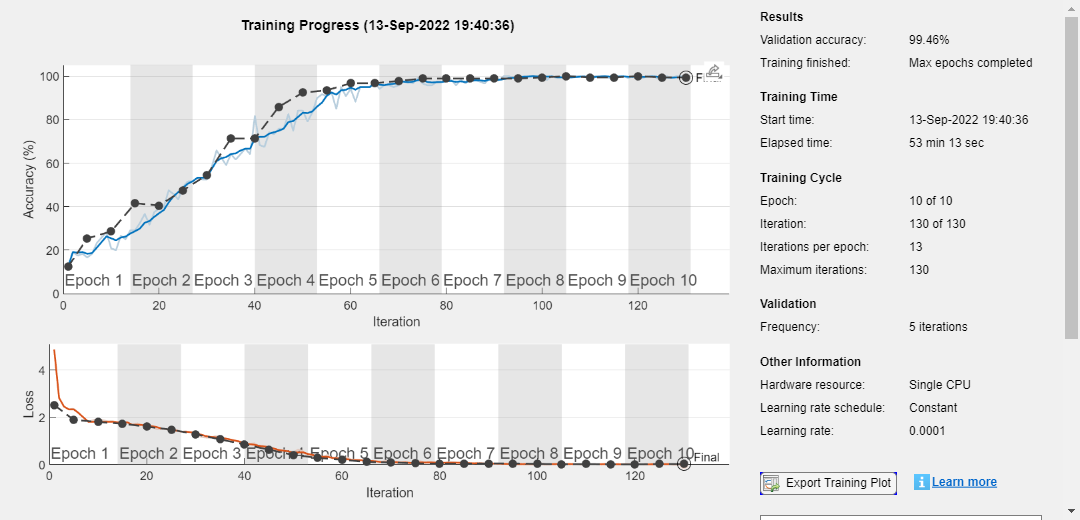

load('googlenetemotion.mat');
gimageInputSize = [224,224,3];
gaugmented_imdsTrain = augmentedImageDatastore(gimageInputSize,imdsTrain);
gaugmented_imdsValid = augmentedImageDatastore(gimageInputSize,imdsValid);
gaugmented_imdsTest = augmentedImageDatastore(gimageInputSize,imdsTest);
soptions=trainingOptions('adam', ...
    'MiniBatchSize',120, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',0.0001, ...
    'ValidationData',gaugmented_imdsValid, ...
    'ValidationFrequency',5,'ValidationPatience',4, ...
    'Plots','training-progress');

%Training
snetTransfer=trainNetwork(gaugmented_imdsTrain,googlenetemotion,soptions);

 
%Testing
[spredicted_labels,spredicted_scores]=classify(snetTransfer,gaugmented_imdsTest);

sPerItemAccuracy = mean(spredicted_labels == actual_labels)

sPerItemAccuracy = 0.9870